# Analogia entre vetores e sinais

## Boas práticas

clc;                    % limpa a tela
clear all;              % limpa as variáveis
close all;              % fecha as figuras

## Descrição do problema

g  = @(t) exp(-t);               % define a função a ser analisada
gn = @(t,n,wo) exp(-j*n*wo*t);   % define a função para decompor o sinal

## Principais variáveis

% wo --> frequência angular fundamnetal
% t  --> variável tempo
% j  --> variável complexa
% n  --> variação da frequência do sinal

## Análise simbólica e numérica

syms t

T0 = 1;
N  = 10;
n =[-N:1:N]

n =    -10    -9    -8    -7    -6    -5    -4    -3    -2    -1     0     1     2     3     4     5     6     7     8     9    10



for k = 1:2*N+1 

g1 = @(t) exp(-t);
g2 = @(n,t) exp(-j*n*2*pi*t);

clc;

c(k) = projecao(g1(t),g2(n(k),t),T0);


end

$$cn = -\frac{{\mathrm{e}}^{-1}\,\left(\mathrm{e}-1\right)}{-1+20\,\pi \,\mathrm{i}}$$

$$cn = -\frac{{\mathrm{e}}^{-1}\,\left(\mathrm{e}-1\right)}{-1+18\,\pi \,\mathrm{i}}$$

$$cn = -\frac{{\mathrm{e}}^{-1}\,\left(\mathrm{e}-1\right)}{-1+16\,\pi \,\mathrm{i}}$$

$$cn = -\frac{{\mathrm{e}}^{-1}\,\left(\mathrm{e}-1\right)}{-1+14\,\pi \,\mathrm{i}}$$

$$cn = -\frac{{\mathrm{e}}^{-1}\,\left(\mathrm{e}-1\right)}{-1+12\,\pi \,\mathrm{i}}$$

$$cn = -\frac{{\mathrm{e}}^{-1}\,\left(\mathrm{e}-1\right)}{-1+10\,\pi \,\mathrm{i}}$$

$$cn = -\frac{{\mathrm{e}}^{-1}\,\left(\mathrm{e}-1\right)}{-1+8\,\pi \,\mathrm{i}}$$

$$cn = -\frac{{\mathrm{e}}^{-1}\,\left(\mathrm{e}-1\right)}{-1+6\,\pi \,\mathrm{i}}$$

$$cn = -\frac{{\mathrm{e}}^{-1}\,\left(\mathrm{e}-1\right)}{-1+4\,\pi \,\mathrm{i}}$$

$$cn = -\frac{{\mathrm{e}}^{-1}\,\left(\mathrm{e}-1\right)}{-1+2\,\pi \,\mathrm{i}}$$

$$cn = 1-{\mathrm{e}}^{-1}$$

$$cn = -\frac{{\mathrm{e}}^{-1}\,\left(\mathrm{e}-1\right)\,\mathrm{i}}{2\,\pi -\mathrm{i}}$$

$$cn = -\frac{{\mathrm{e}}^{-1}\,\left(\mathrm{e}-1\right)\,\mathrm{i}}{4\,\pi -\mathrm{i}}$$

$$cn = -\frac{{\mathrm{e}}^{-1}\,\left(\mathrm{e}-1\right)\,\mathrm{i}}{6\,\pi -\mathrm{i}}$$

$$cn = -\frac{{\mathrm{e}}^{-1}\,\left(\mathrm{e}-1\right)\,\mathrm{i}}{8\,\pi -\mathrm{i}}$$

$$cn = -\frac{{\mathrm{e}}^{-1}\,\left(\mathrm{e}-1\right)\,\mathrm{i}}{10\,\pi -\mathrm{i}}$$

$$cn = -\frac{{\mathrm{e}}^{-1}\,\left(\mathrm{e}-1\right)\,\mathrm{i}}{12\,\pi -\mathrm{i}}$$

$$cn = -\frac{{\mathrm{e}}^{-1}\,\left(\mathrm{e}-1\right)\,\mathrm{i}}{14\,\pi -\mathrm{i}}$$

$$cn = -\frac{{\mathrm{e}}^{-1}\,\left(\mathrm{e}-1\right)\,\mathrm{i}}{16\,\pi -\mathrm{i}}$$

$$cn = -\frac{{\mathrm{e}}^{-1}\,\left(\mathrm{e}-1\right)\,\mathrm{i}}{18\,\pi -\mathrm{i}}$$

$$cn = -\frac{{\mathrm{e}}^{-1}\,\left(\mathrm{e}-1\right)\,\mathrm{i}}{20\,\pi -\mathrm{i}}$$


Res   = 1e-3;               % resolução
tempo = [0:Res:T0];       % vetor tempo
w0    = 2*pi/T0;            % frequência
p0    = c(N+1);             % Neste valor o n é zero

for k=1:N

    p(:,k) = c(N+1-k)*exp(j*n(N+1-k)*w0*tempo) + c(N+1+k)*exp(j*n(N+1+k)*w0*tempo);
    r(:,k) = g1(tempo)' - sum(p(:,k));

end


plot(tempo,g1(tempo)','LineWidth',3);
hold;

Current plot held


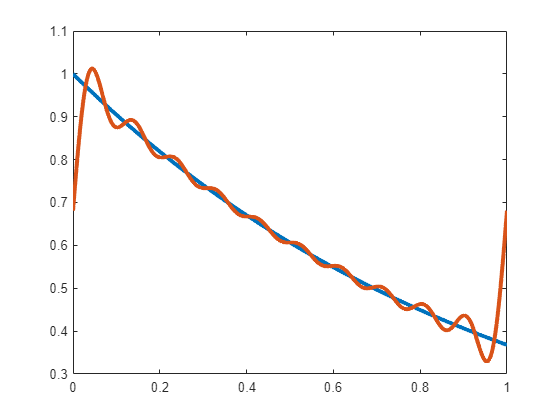

plot(tempo,sum(p')+p0,'LineWidth',3)